# Clase 05 >> Series de Fourier

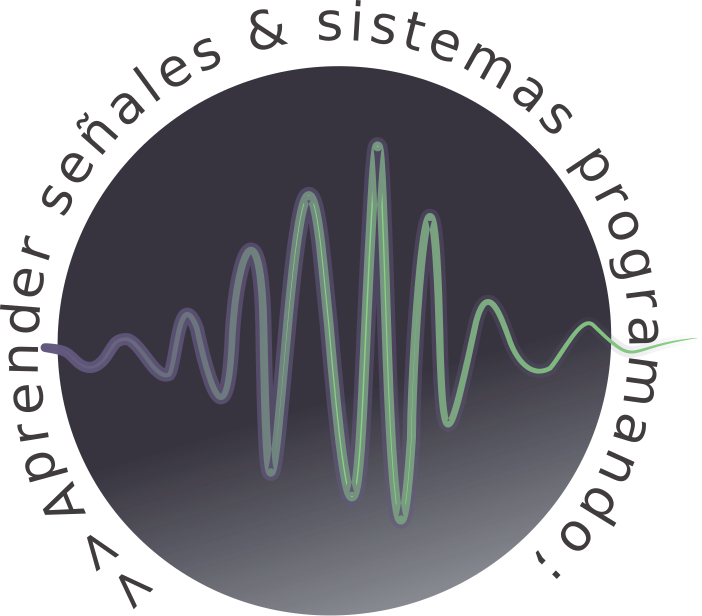

# Temario:

- Una perspectiva historica.

- Teorema de Fourier (suma de ondas senoidales).

- Forma trigonométrica de la serie de Fourier.

- Convergencia de la serie de Fourier. Las condiciones de Dirichlet.

- Efecto de Gibbs. 

- Forma compleja de la serie de Fourier.

- Teorema de Parseval.

En apuntes anteriores observamos que los sistemas LTI pueden ser representados mediante la suma de convolución, la cual se basa en la representación de señales como una combinacion lineal de impulsos desplazados. En éste apunte exploraremos una representación alternativa por medio de la combinación lineal de un conjunto de señales báse.

# Una perspectiva histórica

**Se recomienda la lectura completa del capítulo 3.1 del libro *****Señales y Sistemas*** [Oppenheim A., 1998], para ampliar la lectura de este apartado. El desarrollo del análisis de Fourier tiene una larga historia que involucra a un gran número de personas así como a la investigación de muchos fenómenos físicos diferentes. El concepto fundamental que engloba al análisis de Fourier es el de "sumas trigonométricas" [esto es, las sumas de senos y cosenos relacionados armónicamente]. El interés de representar fenómenos periódicos surge del hecho de describir eventos astronómicos, en términos modernos y más cerca a la disciplina que nos concierne L. Euler estudia las sumas trigonométricas para examinar el movimiento de una cuerda vibratoria. Lo que Euler notó fue que si la configuración de una cuerda vibratoria en algún punto del tiempo es una combinación lineal de los modos normales de la misma, también lo es su configuración en cualquier tiempo subsecuente. Más aún, Euler demostró que se podían calcular los coeficientes de la combinación lineal para un tiempo posterior de una manera muy directa a partir de los coeficientes del tiempo anterior. 

No es hasta 1800 que Jean Baptiste Joseph Fourier aparece en escena (francés nacido en Auxerre en marzo de 1768); en resumidas cuentas sus revolucionarios descubrimientos, aunque no fueron apreciados por completo durante su propia vida, han tenido un gran impacto en el desarrollo de las matemáticas, y además han sido y son todavía de gran importancia en una variedad extremadamente amplia de disciplinas científicas y de la ingeniería. Una nota de color y vale la pena su mención, es que Fourier llevó una vida política muy activa. De hecho, durante los años que siguieron a la Revolución Francesa sus actividades casi lo condujeron a la muerte. Fue colaborador de Napoleón Bonaparte en las campañas a Egipto. 

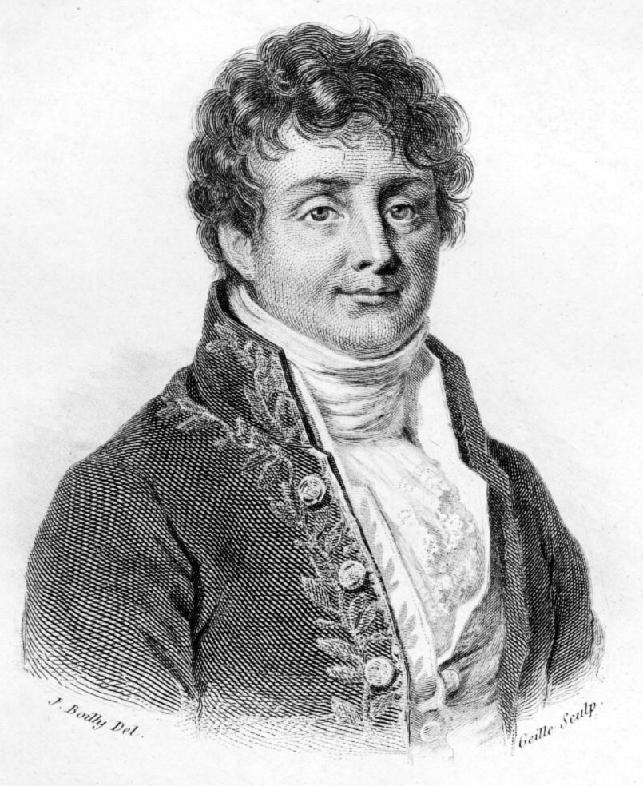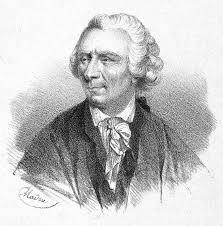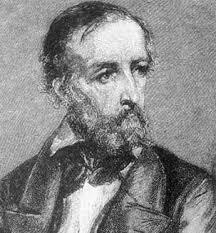

Para aquellos que estudiaron termodinámica estarán familiarizados con los trabajos de Fourier respecto a los fenómenos de propagación y difusión del calor. Para 1807, Fourier había encontrado que algunas series de senoidales relacionadas armónicamente eran útiles para representar la distribución de la temperatura a través de un cuerpo. Adicionalmente, sostenía que "cualquier" señal periódica podía ser representada por tales series, gracias al aporte de otros. Pero su afirmación carecía de sustento matemático y no fue hasta 1829 con la ayuda de P.L. Dirichlet, quien proporcionó las condiciones precisas bajo las cuales una señal periódica podía ser representada con una serie de Fourier.

Recién 15 años después de comenzar con su trabajo de propagación del calor que Fourier pudo publicar en el Instituto de Francia *"Théorie analytique de la chaleur"* un trabajo con muchas controversias y objeciones por parte de los examinadores del trabajo.

# Teorema de Fourier (suma de ondas senoidales)

Este teorema garantiza que una función periódica que satisface ciertas condiciones de continuidad puede ser expresada como suma de un número infinito de funciones senoidales de diferentes amplitudes, fases y períodos. Si retomamos lo aprendido anteriormente sabemos que una señal periódica con periodo $T=\text{ }\frac{2\pi }{\omega }$ tiene la siguiente forma:


$$x\left(t\right)=\text{ }A_O +A_1 sen\left(\omega t+\text{ }\varphi_1 \right)+\text{ }A_2 sen\left(\omega t+\text{ }\varphi_2 \right)+\ldotp \ldotp \ldotp +\text{ }A_n sen\left(\omega t+\text{ }\varphi_n \right)$$


La señal x(t) es una suma finita de señales senoidales, los $A_k$ valores no negativos que representan a las amplitudes, $\omega_k$ las frecuencias en $\frac{rad}{s}$ y $\theta_k$ los ángulos de cada una de las senoides.

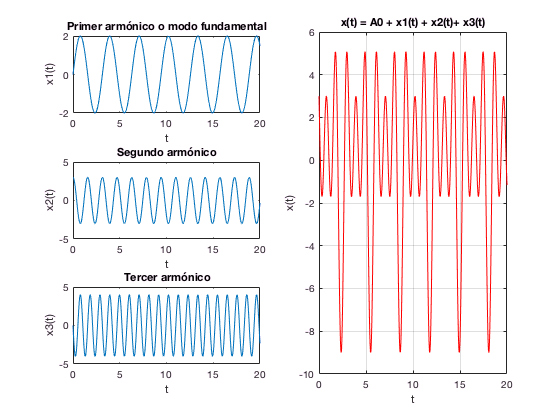

t = linspace(0,20,1000); % vector tiempo
w = 2; % frecuencia fundamental
w1 = 1*w; w2 = 2*w; w3 = 3*w; % armonicos
A0 = 0; % componente de continua
A1 = 2; % amplitudes
A2 = 3;
A3 = 4;
x1 = A1*sin(w1*t);
x2 = A2*sin(w2*t + pi/2);
x3 = A3*sin(w3*t + pi/1);
x = A0 + x1 + x2 + x3;

subplot(3,2,1)
plot(t,x1)
title('Primer armónico o modo fundamental')
xlabel('t')
ylabel('x1(t)')

subplot(3,2,3)
plot(t,x2)
title('Segundo armónico')
xlabel('t')
ylabel('x2(t)')

subplot(3,2,5)
plot(t,x3)
title('Tercer armónico')
xlabel('t')
ylabel('x3(t)')

subplot(3,2,[2,4,6])
plot(t,x,'r')
title('x(t) = A0 + x1(t) + x2(t)+ x3(t)')
xlabel('t')
ylabel('x(t)')
grid on

Es importante destacar el rol que cumplen las amplitudes de las señales componentes de la señal representada como suma de sinusoides. Las mismas especifican de alguna manera los pesos relativos que cada una de ellas tiene en la combinación lineal y puede apreciarse que al variar a las mismas, la forma de onda de la señal también varía a su vez de manera significativa.

Es evidente que las señales resultantes están compuesta de tres frecuencias distintas. Conociendo a las mismas y a sus amplitudes correspondientes puede obtenerse el *espectro de amplitudes* de la señal resultante que no es ni más ni menos que la gráfica de las amplitudes contra las frecuencias. 

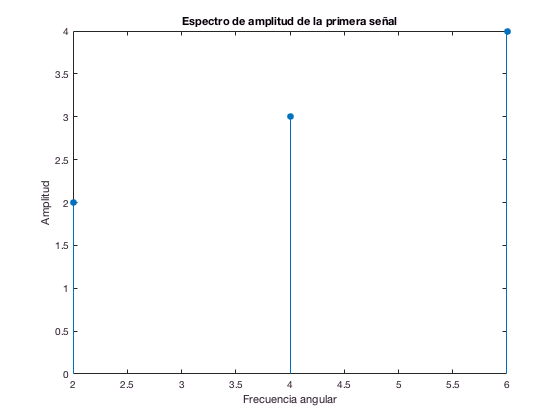

clf
w = [w1, w2, w3];
Am = [A1, A2, A3];
stem(w,Am,'filled')
xlabel('Frecuencia angular')
ylabel('Amplitud')
title('Espectro de magnitudes de la primera señal')

# Forma trigonométrica de la serie de Fourier

Si tomamos el ultimo termino de x(t), entonces:


$$A_n sen\left(n\omega t+\text{ }\varphi_n \right)=\text{ }A_n cos\left(\varphi_n \right)sen\left(n\omega t\right)+A_n sen\left(\varphi_n \right)cos\left(n\omega t\right)=b_n sen\left(n\omega t\right)+\text{ }a_n cos\left(n\omega t\right)$$


Donde:


$$b_n =A_n cos\left(\varphi_n \right),\text{ }a_n =A_n sen\left(\varphi_n \right)$$


De esta manera podemos expresar a $x\left(t\right)$como:


$$x\left(t\right)=\text{ }\frac{1}{2}a_o +\sum_{n=1}^{\infty } a_n cos\left(n\omega t\right)+b_n sen\left(n\omega t\right)$$


Denominada como la **expasión en serie de Fourier**, donde $a_o =2A_o$ valor constante (representa la **componente de continua**), $a_n$ y $b_n$ son los **coeficientes de Fourier**. También es común referirse a $a_n$ y $b_n$ respectivamente como las componentes en fase y en cuadratura de fase del n-ésimo armónico, esta terminología surge del uso de la notación fasorial $e^{jn\omega t} =cos\left(n\omega t\right)+jsen\left(n\omega t\right)$.

Si integramos la serie que presentamos anteriormente con respecto a t sobre un período, obtenemos los coeficientes de Fourier, tambien conocidos como las** fórmulas de Euler:**


$$a_n =\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)cos\left(n\omega t\right)dt,n=0,1,2,\ldotp \ldotp \ldotp$$



$$b_n =\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)sen\left(n\omega t\right)dt,n=0,1,2,\ldotp \ldotp \ldotp$$



$$a_o =\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)dt$$


## Calculando los coeficientes de Fourier

A continuación, se presenta una forma para calcular los coeficientes de la serie trigonométrica de Fourier con el uso del **Symbolic Toolbox**, la cual es herramienta muy útil para trabajar con este tipo de procedimientos de cálculo.

%doc syms

En matemáticas y ciencias de la computación, el **álgebra computacional**, también conocida como **cálculo simbólico** o **cálculo algebraico**, es un área científica que se refiere al estudio y desarrollo de algoritmos y software para la manipulación de expresiones matemáticas y otros objetos matemáticos. Aunque, hablando con propiedad, el álgebra computacional debe ser un sub-campo de la computación científica, ellos son considerados generalmente como campos distintos, porque la **computación científica** se basa generalmente en el análisis numérico con **números aproximados en punto flotante**; mientras que, el **álgebra computacional **enfatiza el **cálculo *****exacto***** con expresiones que contengan variables que no tienen cualquier valor dado y por lo tanto son manipulados como símbolos (de ahí se debe el nombre de *****cálculo simbólico*****).**

**Ejemplo,** obtener la expansion en serie de Fourier de la función periódica f(t) de período $2\pi$ definida por:


$$x(t)=t \text{ (0<t<2\pi ),\text{  x(t)=x(t+2\pi) }$$


- Graficar función

En primer lugar, es conveniente tener una noción visual de la apariencia de la señal con la que se está trabajando, por lo que se procede a relizar una gráfica del periodo establecido de la misma. 

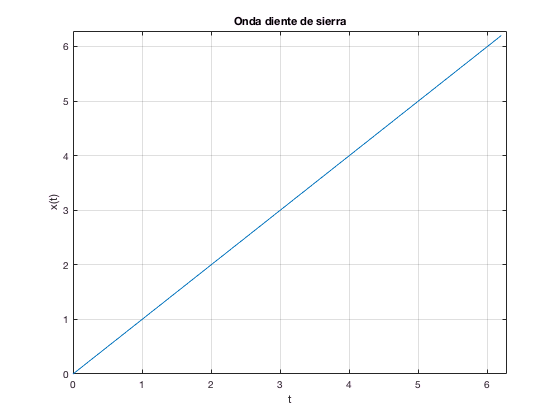

clf
x = 0:0.1:2*pi;
y = x;
plot(x,y)
title('Onda diente de sierra')
ylabel('x(t)')
xlabel('t')
xlim([0 2*pi])
ylim([0 2*pi])
grid on

- Establecer variables simbolicas, período y frecuencia angular

Se define, en una primera instancia, a la variable simbólica t, y la variable simbólica n.

syms t n
assume(n,'integer')

Se establecen, en segundo lugar, el período de la función y su frecuencia angular.

El periodo de esta función en particular es $2\pi$ y su frecuencia angular 1.

A = [0 2*pi]; % Vector útil que especifica los intervalos de la función a trozos.
T = max(A) - min(A);
wo = 2*pi/T;

- Calcular los coeficientes de la serie de Fourier

Ao = int(t,'t',0,2*pi);
Ao = simplify((Ao*2)/T)

$$Ao = 2\,\pi$$

An = int(t*cos(wo*t*n),'t',0,2*pi);
An = simplify((An*2)/T)

$$An = 0$$

Bn = int(t*sin(wo*t*n),'t',0,2*pi);
Bn = simplify((Bn*2)/T)

$$Bn = -\frac{2}{n}$$


$$x\left(t\right)=\frac{1}{2}a_o +\sum_{n=1}^{\infty } a_n cos\left(n\omega t\right)+b_n sen\left(n\omega t\right)=\pi −\sum_{k=1}^{\infty } \frac{2}{n}sen\left(nt\right)$$


## Ejercicios de la guía "Series de Fourier" (script_sf_1)

Resolver el ejercicio n°1, nº4 y nº5 con un script en MATLAB.

Ejemplo, en el ejercicio nº1 dada la función $f\left(t\right)=e^{−4t}$ para $−2\le t\le 2$. Graficar f y hallar el desarrollo en serie de Fourier de $f\left(t\right)$.

% script_sf_1()

# Convergencia de la serie de Fourier. Las condiciones de Dirichlet

Fourier estaba convencido de que todas las señales periódicas eran capaces de ser expresadas como una suma de sinusoides. Su postura era controversial ya que afirmaba que señales "con esquinas", como una triangular o rectangular, podía ser expresada como tal. Los senos y cosenos son funciones que tienen existencia de derivada de cualquier orden, lo cual hacía dificil de creer que con ellas se pudiera representar a funciones con discontinuidades, lo cual resultó ser cierto. Dirichlet demostró posteriormente que una señal periódica tiene representación en series de Fourier si cumple las siguientes condiciones que llevan su nombre: 

Si $f\left(t\right)$ es una función periódica que en cualquier período tiene:

- No debe tener más que un número finito de máximos y mínimos en cualquier periodo de la señal.

- Sólo debe tener un número finito de discontinuidades en cada periodo. 

- Debe ser absolutamente integrable sobre cualquier periodo, osea


$$\int_T |x\left(t\right)dt\text{ }<\text{ }\infty \text{ }|$$


Un ejemplo de una funcion que no cumple las condiciones de Dirichlet es:


$$x\left(t\right)=\frac{1}{3−t}$$


syms t
x = sym(1/(3-t))

$$x = -\frac{1}{t-3}$$

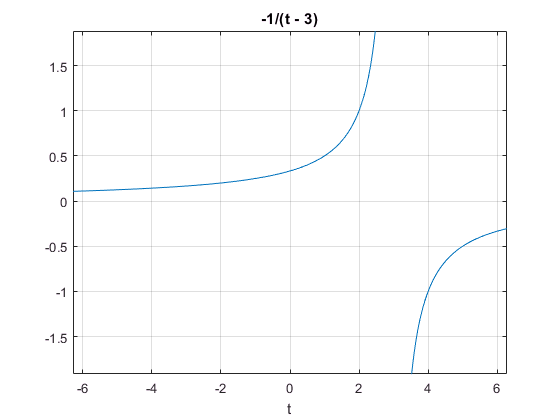

ezplot(x)
ylabel('x(t)')
xlabel('t')
grid on

Tiene una asíntota vertical en t = 3 que está dentro del intervalo dado que la señal no existe en ese valor.

## Ejemplo práctico

Un ejemplo de señal útil y práctica para el desarrollo de la serie podría ser un tren de pulsos como el definido por la siguiente expresión:


$$f\left(t\right)=\left\lbrace \begin{array}{c}
1 & si|t|<0\ldotp 5\\
0 & si\text{ }0\ldotp 5\text{ }<|t|<1
\end{array}\right.$$


La expresión indica un periodo de la señal, se sobreentiende que la misma repite el patrón indefinidamente tanto para valores mayores como menores de t. 

En primer lugar, es conveniente tener una noción visual de la apariencia de la señal con la que se está trabajando, por lo que se procede a relizar una gráfica del periodo establecido de la misma. 

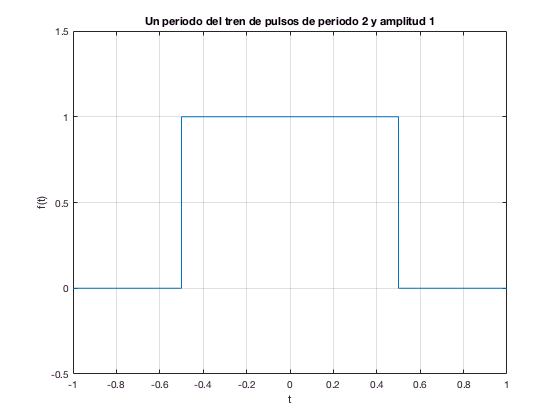

A = [-1 -0.5 0.5 1]; % Vector útil que especifica los intervalos de la función a trozos.
x = min(A):0.0001:max(A);
fx = (x<0.5 & x>-0.5);
plot(x,fx)
title('Un periodo del tren de pulsos de periodo 2 y amplitud 1')
ylabel('f(t)')
xlabel('t')
xlim([-1 1])
ylim([-0.5 1.5])
grid on

Se define, en una primera instancia, a la variable simbólica t, a la variable simbólica n y a la función simbólica f.

syms t n
assume(n,'integer')
f = [0 1 0];
f = sym(f)

$$f = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

Se establecen, en segundo lugar, el período de la función a trozos y su frecuencia angular.

El periodo de esta función en particular es 8.

T = max(A) - min(A);
wo = 2*pi/T;
wo = sym(wo)

$$wo = \pi$$

Se procede al cálculo de los coeficientes de la serie de Fourier con la ayuda de bucles for.

Primero, el término constante definido por


$$a_o =\frac{1}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} f\left(t\right)dt$$


Ao = 0;
for i=1:length(f)
    Ao = Ao + int(f(i),'t',A(i),A(i+1));
end
Ao = simplify(Ao*2/T)

$$Ao = 1$$

Se continúa con el cálculo de los coeficientes correspondientes a la sumatoria de los cosenos, definidos como:


$$a_n =\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} f\left(t\right)cos\left(n\omega t\right)dt$$


An = 0;
for i=1:length(f)
    An = An + int(f(i)*cos(n*wo*t),'t',A(i),A(i+1));
end
An = simplify(An*2/T)

$$An = \frac{2\,\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

Por último, resta calcular los coeficientes correspondientes a la sumatoria de senos definidos como


$$b_n =\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} f\left(t\right)sen\left(n\omega t\right)dt$$


Bn = 0;
for i=1:length(f)
    Bn = Bn + int(f(i)*sin(n*wo*t),'t',A(i),A(i+1));
end
Bn = simplify(Bn*2/T)

$$Bn = 0$$

Ahora, conociendo los coeficientes de la serie de Fourier puede escribirse la representación de la señal como indica la expresión general vista anteriormente. La misma quedaría, entonces:


$$f\left(t\right)=\frac{1}{2}+\sum_{n=1}^{\infty \text{ }} 2\frac{sen\left(\frac{\pi n}{2}\right)}{\pi n}cos\left(\frac{n\pi t}{2}\right)$$


Se procede a calcular la representación en series de Fourier del tren de pulsos con los coeficientes obtenidos. Primero, se vectorizan los coeficientes y luego se ejecutan los cálculos pertinentes según la definición de la serie. 

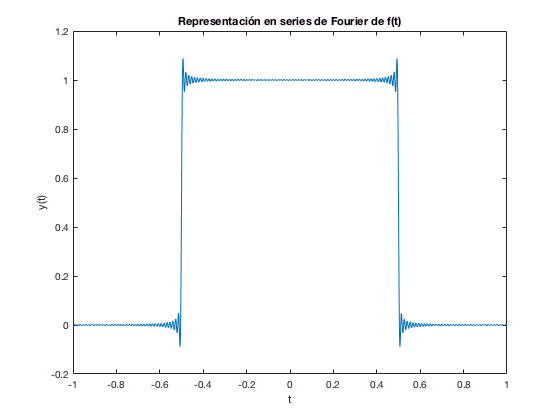

An(n) = sym(An);
wo =  double(wo);
Ar = 150; % cantidad de armónicos.
A_n = zeros(1,Ar);
for i=1:Ar
    A_n(1,i) = An(i); % Se van llenando en A_n los valores de cada uno de los coeficientes.
end

A_n = double(A_n);

x = min(A):0.001:max(A); % vector temporal
cosSum = zeros(1,length(x));

for i = 1:Ar
    cosSum = cosSum + A_n(1,i)*cos(i*wo*x);
end

Ao = double(Ao);
y =  Ao/2 + cosSum;

clf
plot(x,y)
title('Representación en series de Fourier de f(t)')
xlabel('t')
ylabel('y(t)')

# Efecto de Gibbs

Se observa en la suma parcial elaborada anteriormente que en la zona de las discontinuidades se presentan rizos. Este efecto conocido como **fenómeno de Gibbs** ocurre siempre que existan discontinuidades. Gibbs demostró que, para estos casos, la suma parcial puede alcanzar un valor hasta un 18% más grande que el de la discontinuidad sin importar la cantidad de armónicos que se utilicen para la suma. Conforme se aumenten la cantidad de armónicos los rizos tenderán a comprimirse hacia la discontinuidad.

El porcentaje de Gibbs se calcula a continuación:

porcentajeDeGibbs = abs((max(y)-max(fx(1,:)))*2)/(max(fx(1,:))-min(fx(1,:)))*100

porcentajeDeGibbs = 17.6580

El  procedimiento descrito anteriormente puede utilizarse para representar mediante sumas parciales de Fourier a cualquier otra función que el alumno desee representar. Se los invita a probar distintas funciones (a trozos o no), para distintos intervalos y con diferente cantidad de armónicos para familiarizarse con el concepto de las series de Fourier. 

# Forma compleja de la serie de Fourier

La importancia de las series de Fourier radica en el hecho de que, de manera general, cualquier señal periódica de interés práctico puede ser representada como tal; es decir, como una suma ponderada de exponenciales complejas relacionadas armónicamente que comparten un período en común con la señal a representar, como se muestra a continuación:

Partiendo de la forma trigonometrica y reemplazando por:


$$sen\left(n\omega t\right)=\frac{1}{2i}\left(e^{in\omega t} −e^{−in\omega t} \right)$$



$$cos\left(n\omega t\right)=\frac{1}{2}\left(e^{in\omega t} +e^{−in\omega t} \right)$$


Se obtiene la **ecuación de síntesis:**


$$f\left(t\right)=\sum_{k=−\infty }^{+\infty } c_k e^{jk\omega_o t}$$


Los coeficientes de la combinación lineal pueden conocerse mediante:


$$c_k =\frac{1}{T}\int_T f\left(t\right)e^{−jk\omega_o t} dt$$


que se conoce como **ecuación de análisis**. 

**Ejemplo**, se calculan los coeficientes de la serie en forma exponencial de Fourier del tren de pulsos definido anteriormente.

syms ck t n
f = [0 1 0];
f = sym(f)

$$f = \left(\begin{array}{ccc} 0 & 1 & 0 \end{array}\right)$$

A = [-4 -2 2 4];
T = max(A) - min(A);
wo = 2*pi/T;
wo = sym(wo);

Cn = 0;
for i=1:length(f)
    Cn = Cn + int(f(i)*exp(-j*n*wo*t),'t',A(i),A(i+1));
end
Cn = simplify(Cn*1/T)

$$Cn = \frac{\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

Los coeficientes $c_k$ pueden calcularse a partir de los coeficientes de la serie trigonométrica de Fourier de la siguiente manera:

                                                               $c_0 =a_0$; $c_k =\frac{1}{2}\left(a_k −jb_k \right);$ $c_{−k} =\text{ }\frac{1}{2}\left(a_k +jb_k \right)$

En el caso del tren de pulsos, 


$$c_k =\frac{1}{2}a_k$$


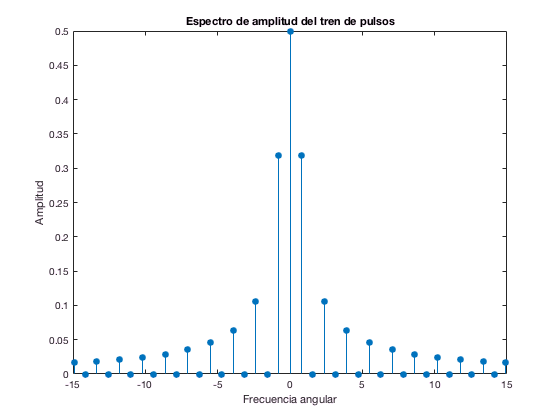

% Espectros de línea.

c_n = [1/2*fliplr(A_n),Ao, 1/2*A_n]; % Se agrega Ao.
wn = (-Ar:Ar)*wo;
stem(wn,(abs(c_n)),'filled')
title('Espectro de magnitudes del tren de pulsos')
xlabel('Frecuencia angular')
ylabel('Magnitud')
xlim([-15 15])

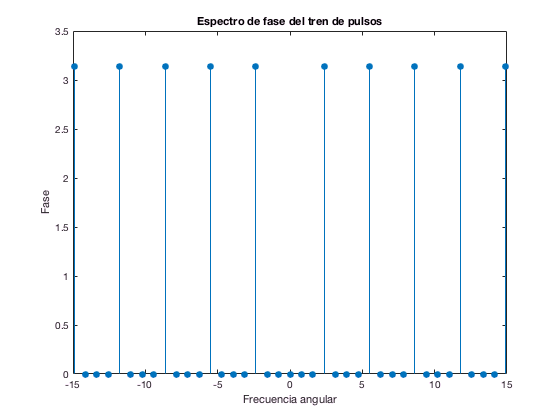


stem(wn,(angle(c_n)),'filled')
title('Espectro de fase del tren de pulsos')
xlabel('Frecuencia angular')
ylabel('Fase')
xlim([-15 15])

## Ejercicios de la guía "Series de Fourier" (script_sf_2)

Resolver el ejercicio n°6, nº7 y nº8 con un script en MATLAB.

Ejemplo, en el ejercicio nº7, hallar la serie trigonom´etrica de Fourier para la senal onda triangular peri´odica mostrada en la siguiente figura

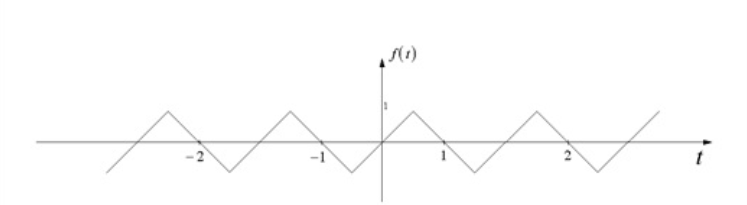

% script_sf_2()

# Teorema de Parseval

Si $f\left(t\right)$ es una función periódica de periodo T entonces:


$$\frac{1}{T}\int_T {\left\lbrack f\left(t\right)\right\rbrack }^2 dt=\sum_{−\infty }^{\infty } c_n {c_n }^∗ =\text{ }\sum_{−\infty }^{\infty } |c_n |^2$$


Donde ${c_n }^∗$ es el conjugado de $c_n$. 

Este teorema nos permite calcular la integral de ${\left\lbrack f\left(t\right)\right\rbrack }^2$ mediante los coeficientes complejos $c_n$ de Fourier de la función periódica $f\left(t\right)$.

También existe la expresión de la identidad de Parseval para la forma trigonométrica de Fourier:


$$\frac{2}{T}\int_{−\frac{T}{2}}^{\frac{T}{2}} |f\left(x\right)|^2 dx=\text{ }\frac{a_o^2 }{2}+\text{ }\sum_{n=1}^{\infty } {\left(a_n +b_n \right)}^2$$


**Ejemplo**, el teorema de Parseval puede resultar útil para hallar el valor de algunas series infintas cuyo cálculo directo resulta dificultoso. Se demostrará que 


$$\frac{1}{2}=\sum_{n=1}^{\infty } \frac{{\left(1−{\left(−1\right)}^n \right)}^2 }{\pi n^2 }$$


al aplicar el teorema de Parseval a la siguiente señal periódica continua


$$f\left(t\right)=\text{ }\left\lbrace \begin{array}{c}
1 & si\text{ }0<t<\frac{\pi }{2}\\
0 & si\text{ }\frac{\pi }{2}<t<\pi 
\end{array}\right.$$


- Calcular los coeficientes reales de Fourier de f(t):

syms t n
assume(n,'integer')
f = [1 0];
A = [0 pi/2 pi];
f = sym(f);
T = max(A) - min(A)

T = 3.1416

wo = 2*pi/T

wo = 2

wo = sym(wo);

- Calcular el coeficiente continuo $a_o$:

Ao = 0;
for i=1:length(f)
    Ao = Ao + int(f(i),'t',A(i),A(i+1));
end
Ao = simplify(2*Ao/T)

$$Ao = 1$$

- Ahora, los coeficientes $a_n$:

An = 0;
for i=1:length(f)
    An = An + int(f(i)*cos(n*wo*t),'t',A(i),A(i+1));
end
An = simplify(An*2/T)

$$An = 0$$

- Ahora, los coeficientes $b_n$:

Bn = 0;
for i=1:length(f)
    Bn = Bn + int(f(i)*sin(n*wo*t),'t',A(i),A(i+1));
end
Bn = simplify(Bn*2/T,'Steps',100)

$$Bn = -\frac{{\left(-1\right)}^{n}-1}{n\,\pi }$$

Al utilizar la relación de Parseval:


$$\frac{2}{\pi }\int_0^{\frac{\pi }{2}} dt=\frac{1}{2}+\sum_{n=1}^{\infty } \frac{{\left(1−{\left(−1\right)}^n \right)}^2 }{{\left(\pi n\right)}^2 }$$


resulta en:


$$\frac{1}{2}=\sum_{n=1}^{\infty } \frac{{\left(1−{\left(−1\right)}^n \right)}^2 }{{\left(\pi n\right)}^2 }$$


## Referencias

- Oppenheim, Alan V.; Willsky, Alan S.; Nawab, S. Hamid. ***Señales y sistemas***. Pearson Educación, 1998.

- Glyn, James. **Matemáticas Avanzadas para Ingeniería**. 2002.

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.